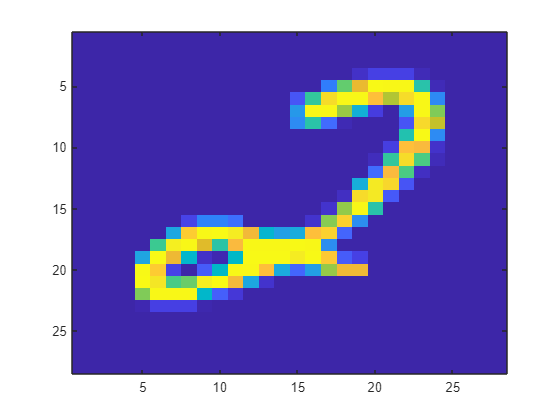

import mnist.mat.*
mean=(zeros(28*28, 1 ,10));
cov1=zeros(28*28, 28*28, 10);
shape1=(zeros(28*28, 1, 60000));
shape1=reshape(digits_train, size(shape1));
mean=double(mean);
cov1=double(cov1);
shape1=double(shape1);

for i=1:60000
    mean(:, 1, labels_train(i, 1)+1)=(mean(:, 1, labels_train(i, 1)+1)+shape1(:, 1, i))/sum(labels_train(:,1)==labels_train(i, 1));
end
for i=1:60000
    cov1(:,:,labels_train(i, 1)+1)=(cov1(:,:,labels_train(i, 1)+1)+((shape1(:,1,i)-mean(:,1,labels_train(i, 1)+1))*(shape1(:,1,i)-mean(:,1,labels_train(i, 1)+1))'))/sum(labels_train(:,1)==labels_train(i, 1));
end

shape2=reshape(mean(:, :, 3), [28,28]);
imagesc(shape2);

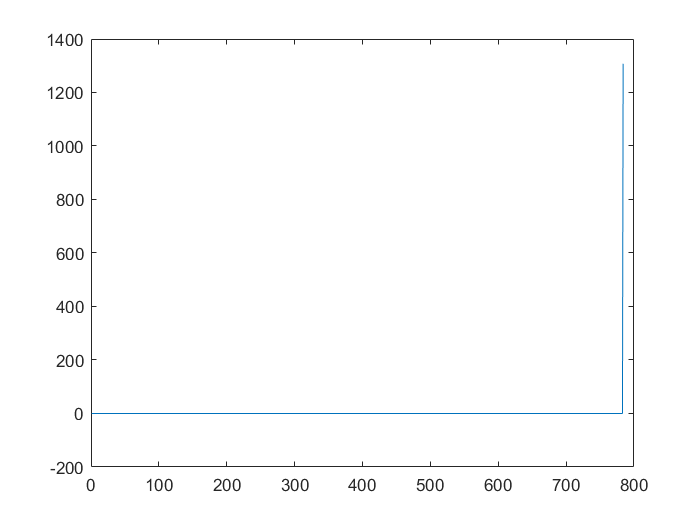


eigenVal1=zeros(28*28, 28*28, 10);
eigenVal1=double(eigenVal1);
eigenVec=zeros(28*28,28*28, 10);
for j=1:10
    [eigenVec(:,:,j),eigenVal1(:,:,j)]=eig(cov1(:, :, j));
end
eigenVal=zeros(28*28, 1, 10);
for k=1:10
    eigenVal(:,1,k)=diag(eigenVal1(:,:,k));
end
SortEig=sort(eigenVal, 1);
%SortEig(:,:,1)
plot(SortEig(:, :, 1));

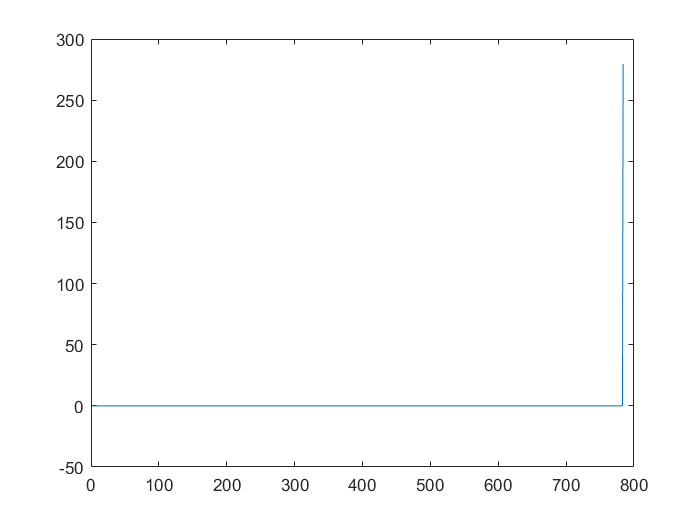

plot(SortEig(:, :, 2));

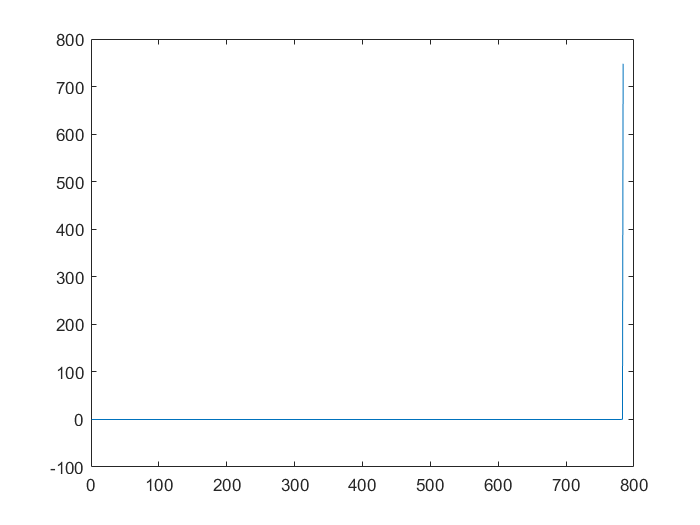

plot(SortEig(:, :, 3));

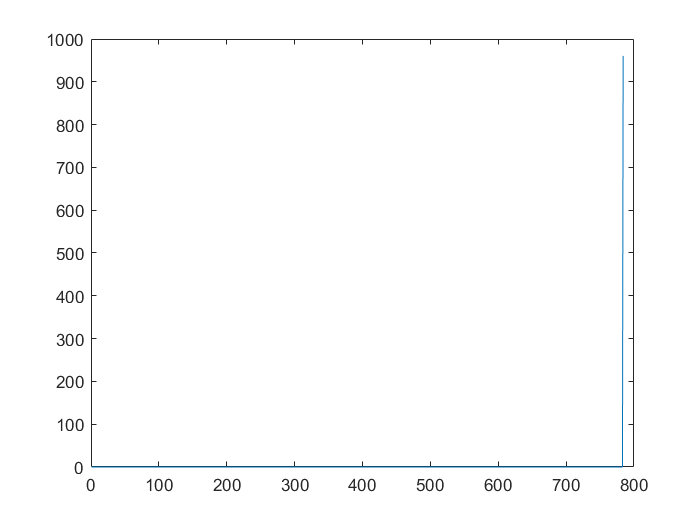

plot(SortEig(:, :, 4));

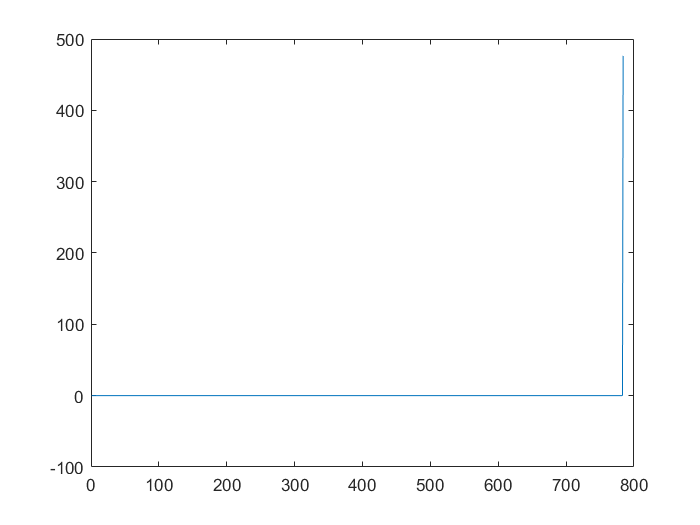

plot(SortEig(:, :, 5));

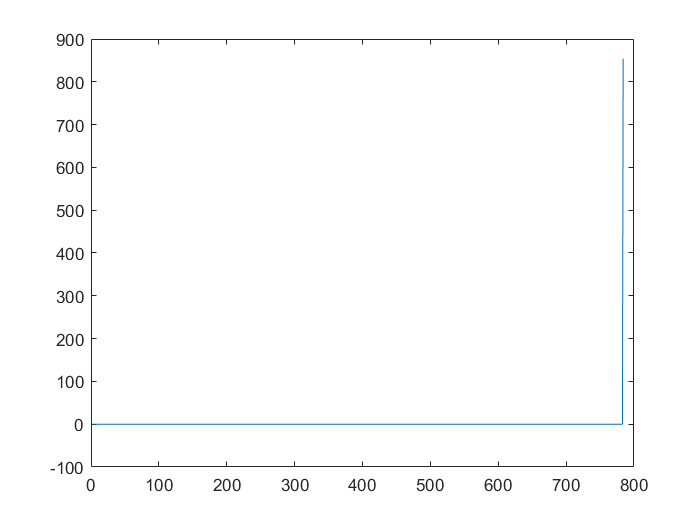

plot(SortEig(:, :, 6));

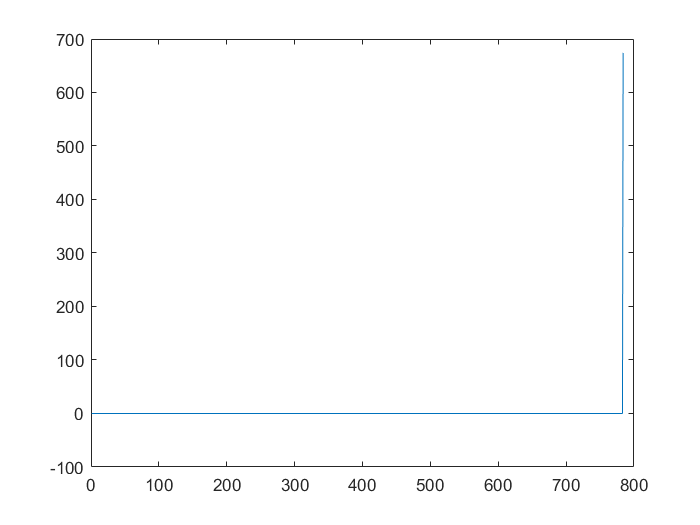

plot(SortEig(:, :, 7));

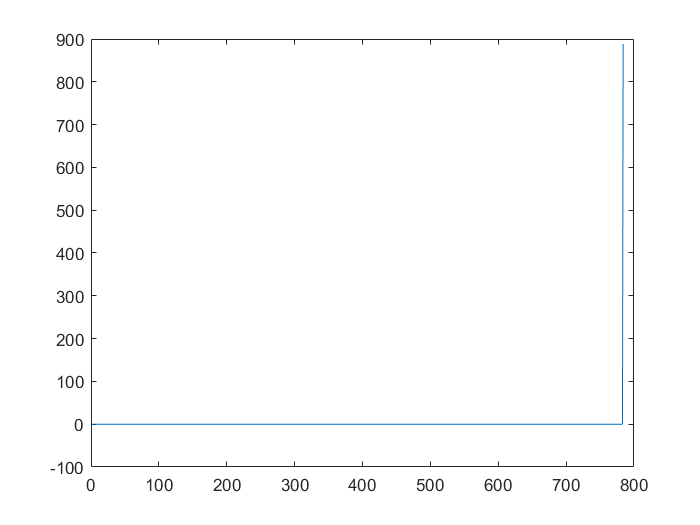

plot(SortEig(:, :, 8));

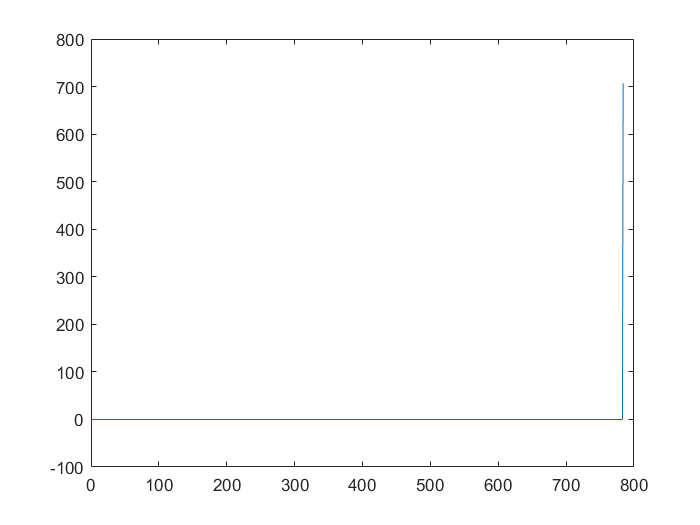

plot(SortEig(:, :, 9));

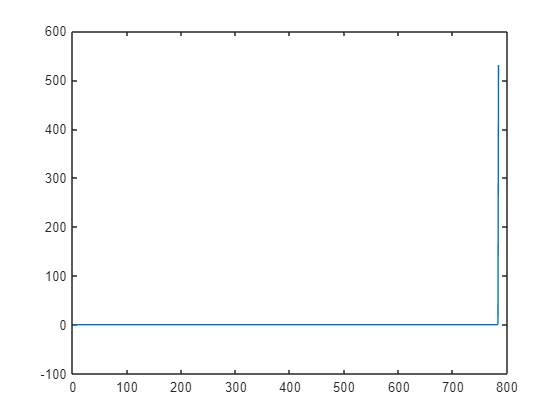

plot(SortEig(:, :, 10));

ans =   handle to deleted Graphics


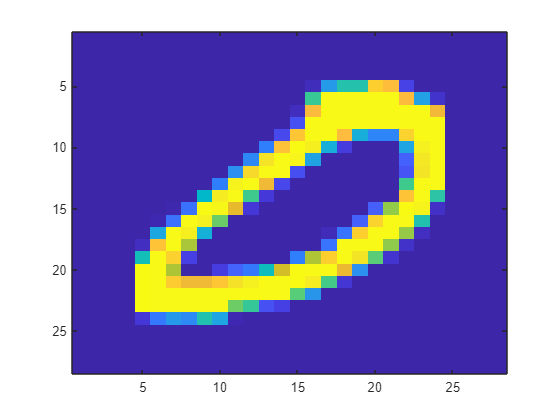


subplot(1, 3, 1), imagesc((reshape((mean(:,1,1)-(sqrt(eigenVal(28*28,1,1))).*eigenVec(:,28*28, 1)),[28,28])));

ans =   handle to deleted Graphics


subplot(1, 3, 2), imagesc((reshape(mean(:,1,1),[28,28])));

ans =   handle to deleted Graphics


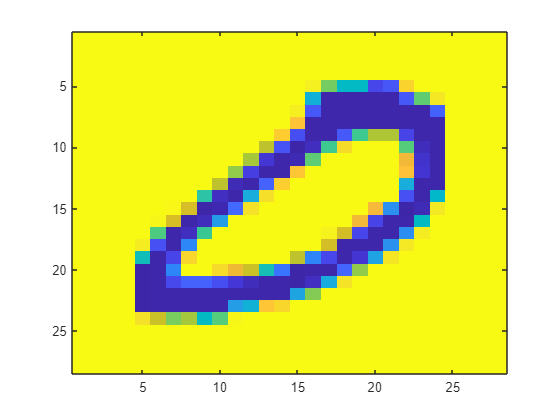

subplot(1, 3, 3), imagesc((reshape((mean(:,1,1)+(sqrt(eigenVal(28*28,1,1))).*eigenVec(:,28*28, 1)),[28,28])));

ans =   handle to deleted Graphics


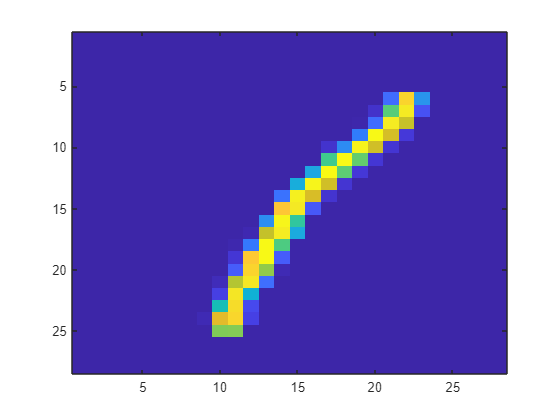


subplot(1, 3, 1), imagesc((reshape((mean(:,1,2)-(sqrt(eigenVal(28*28,1,2))).*eigenVec(:,28*28, 2)),[28,28])));

ans =   handle to deleted Graphics


subplot(1, 3, 2), imagesc((reshape(mean(:,1,2),[28,28])));

ans =   handle to deleted Graphics


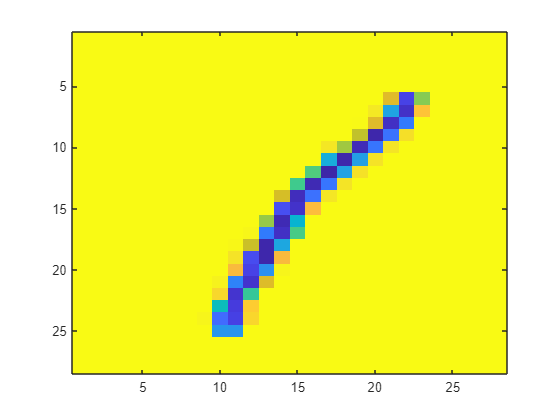

subplot(1, 3, 3), imagesc((reshape((mean(:,1,2)+(sqrt(eigenVal(28*28,1,2))).*eigenVec(:,28*28, 2)),[28,28])));

ans =   handle to deleted Graphics



subplot(1, 3, 1), imagesc((reshape((mean(:,1,3)-(sqrt(eigenVal(28*28,1,3))).*eigenVec(:,28*28, 3)),[28,28])));

ans =   handle to deleted Graphics


subplot(1, 3, 2), imagesc((reshape(mean(:,1,3),[28,28])));

ans =   handle to deleted Graphics


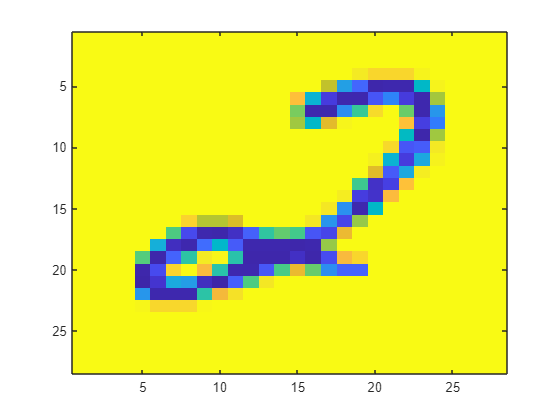

subplot(1, 3, 3), imagesc((reshape((mean(:,1,3)+(sqrt(eigenVal(28*28,1,3))).*eigenVec(:,28*28, 3)),[28,28])));

ans =   handle to deleted Graphics


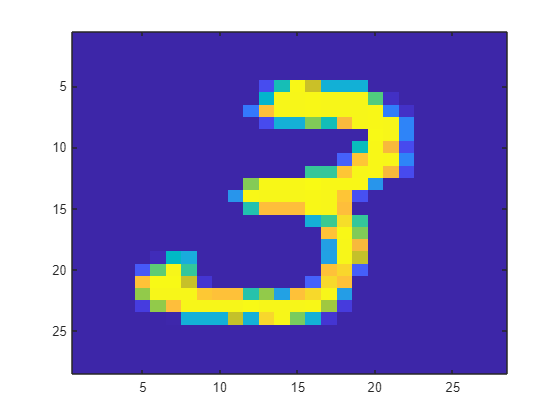


subplot(1, 3, 1), imagesc((reshape((mean(:,1,4)-(sqrt(eigenVal(28*28,1,4))).*eigenVec(:,28*28, 4)),[28,28])));

ans =   handle to deleted Graphics


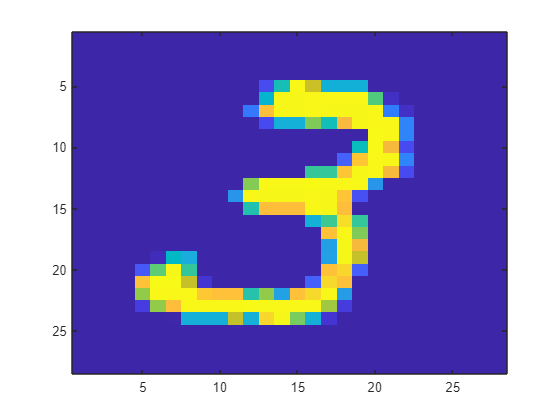

subplot(1, 3, 2), imagesc((reshape(mean(:,1,4),[28,28])));

ans =   handle to deleted Graphics


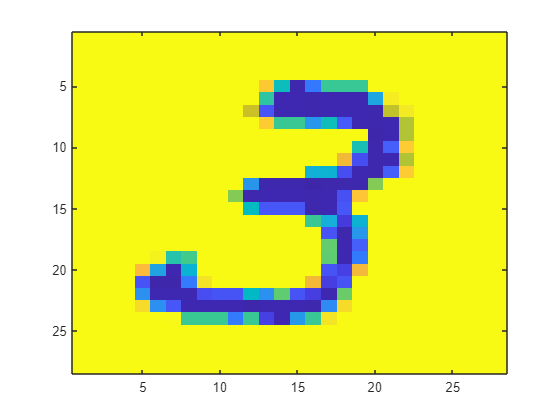

subplot(1, 3, 3), imagesc((reshape((mean(:,1,4)+(sqrt(eigenVal(28*28,1,4))).*eigenVec(:,28*28, 4)),[28,28])));

ans =   handle to deleted Graphics


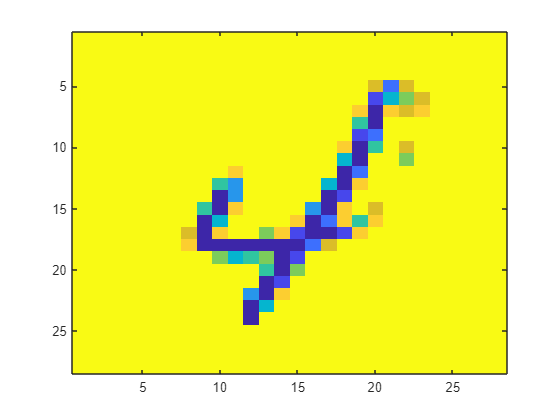


subplot(1, 3, 1), imagesc((reshape((mean(:,1,5)-(sqrt(eigenVal(28*28,1,5))).*eigenVec(:,28*28, 5)),[28,28])));

ans =   handle to deleted Graphics


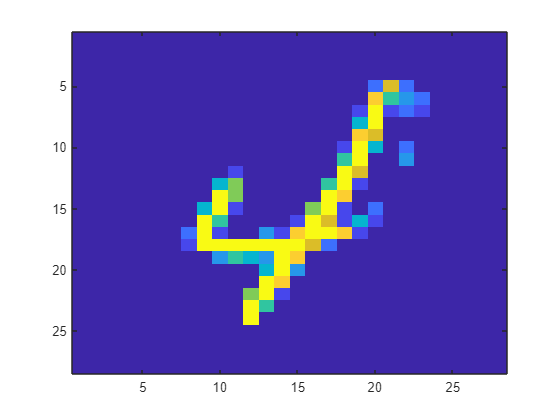

subplot(1, 3, 2), imagesc((reshape(mean(:,1,5),[28,28])));

ans =   handle to deleted Graphics


subplot(1, 3, 3), imagesc((reshape((mean(:,1,5)+(sqrt(eigenVal(28*28,1,5))).*eigenVec(:,28*28, 5)),[28,28])));

ans =   handle to deleted Graphics


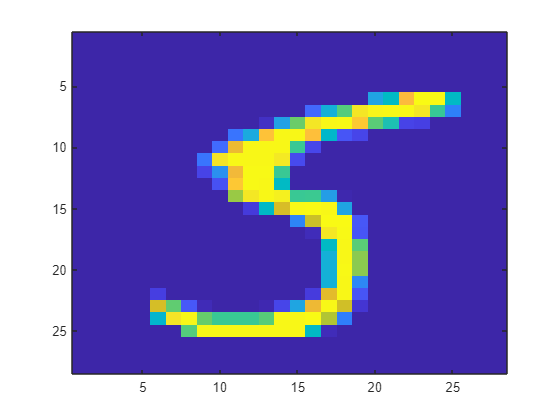


subplot(1, 3, 1), imagesc((reshape((mean(:,1,6)-(sqrt(eigenVal(28*28,1,6))).*eigenVec(:,28*28, 6)),[28,28])));

ans =   handle to deleted Graphics


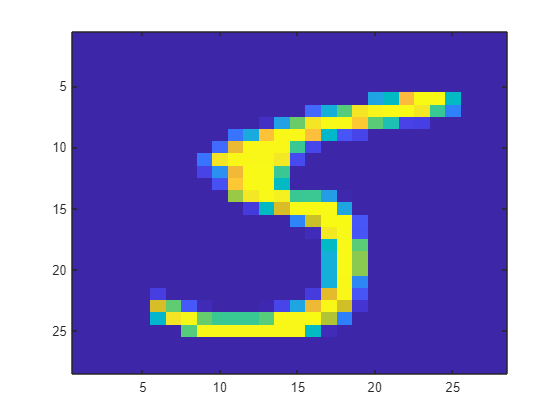

subplot(1, 3, 2), imagesc((reshape(mean(:,1,6),[28,28])));

ans =   handle to deleted Graphics


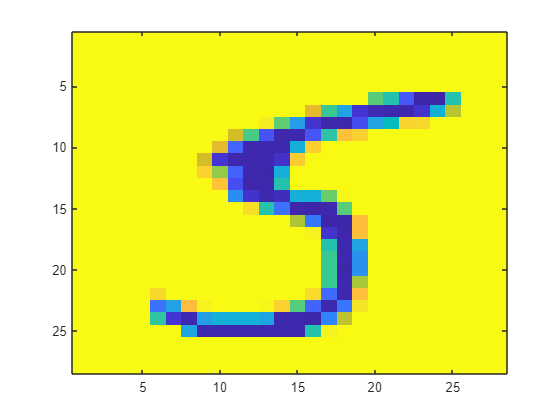

subplot(1, 3, 3), imagesc((reshape((mean(:,1,6)+(sqrt(eigenVal(28*28,1,6))).*eigenVec(:,28*28, 6)),[28,28])));

ans =   handle to deleted Graphics


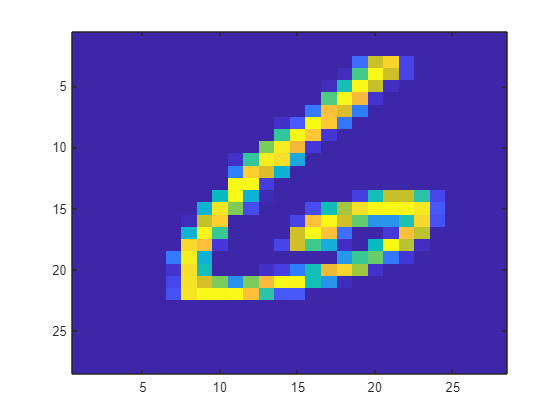


subplot(1, 3, 1), imagesc((reshape((mean(:,1,7)-(sqrt(eigenVal(28*28,1,7))).*eigenVec(:,28*28, 7)),[28,28])));

ans =   handle to deleted Graphics


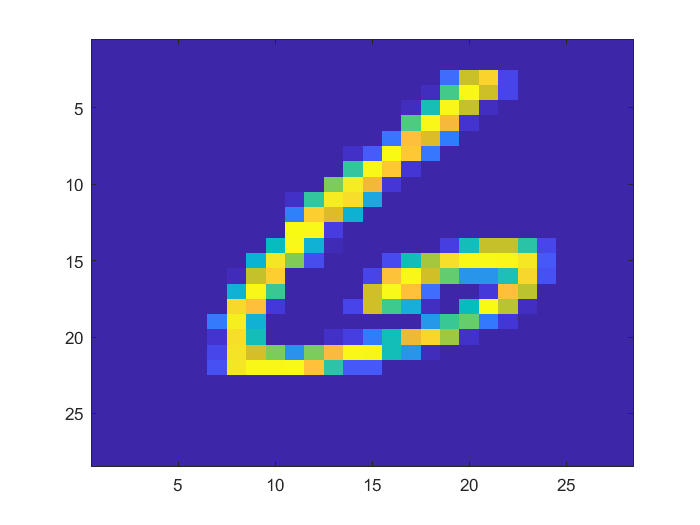

subplot(1, 3, 2), imagesc((reshape(mean(:,1,7),[28,28])));

ans =   handle to deleted Graphics


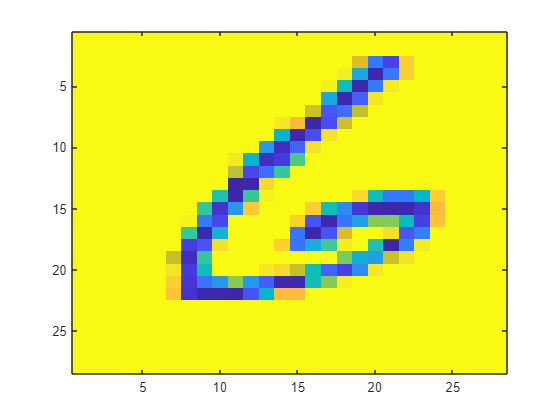

subplot(1, 3, 3), imagesc((reshape((mean(:,1,7)+(sqrt(eigenVal(28*28,1,7))).*eigenVec(:,28*28, 7)),[28,28])));

ans =   handle to deleted Graphics


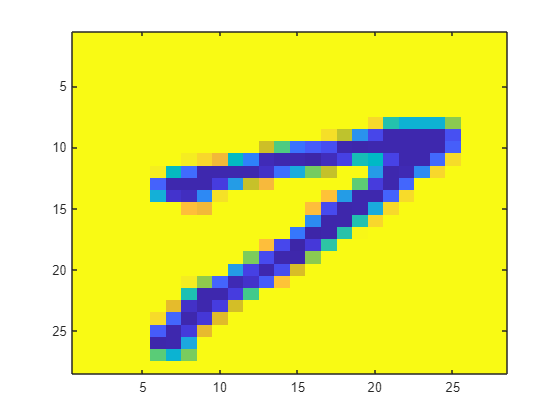


subplot(1, 3, 1), imagesc((reshape((mean(:,1,8)-(sqrt(eigenVal(28*28,1,8))).*eigenVec(:,28*28, 8)),[28,28])));

ans =   handle to deleted Graphics


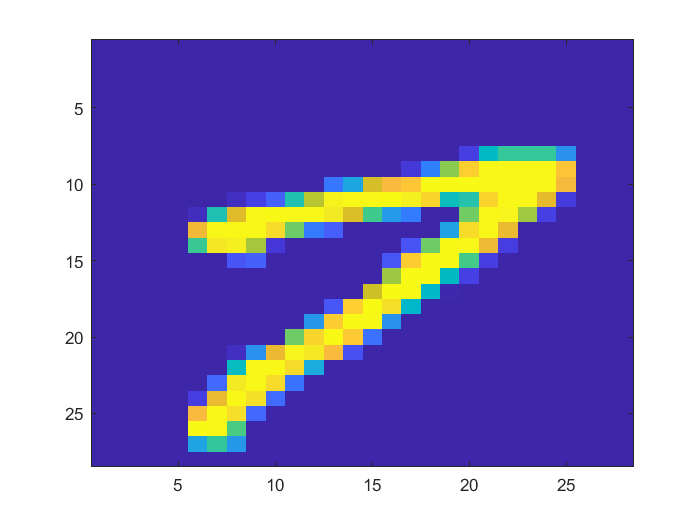

subplot(1, 3, 2), imagesc((reshape(mean(:,1,8),[28,28])));

ans =   handle to deleted Graphics


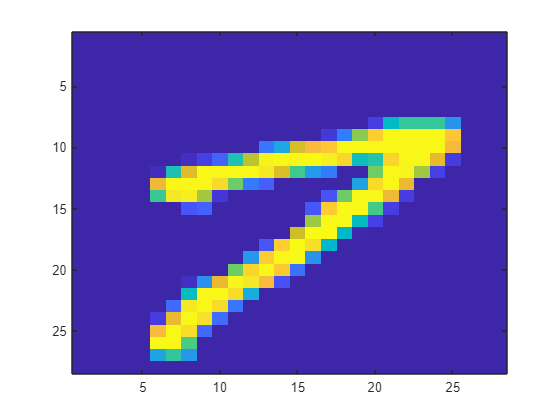

subplot(1, 3, 3), imagesc((reshape((mean(:,1,8)+(sqrt(eigenVal(28*28,1,8))).*eigenVec(:,28*28, 8)),[28,28])));

ans =   handle to deleted Graphics


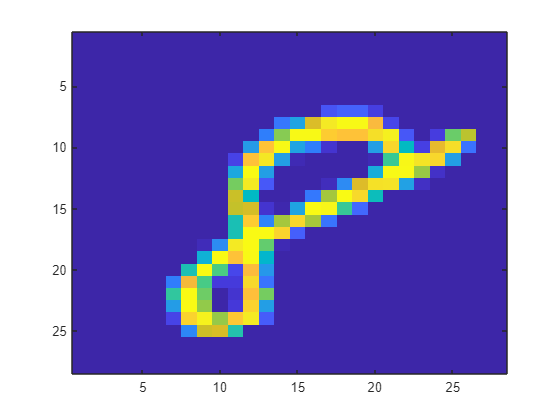


subplot(1, 3, 1), imagesc((reshape((mean(:,1,9)-(sqrt(eigenVal(28*28,1,9))).*eigenVec(:,28*28, 9)),[28,28])));

ans =   handle to deleted Graphics


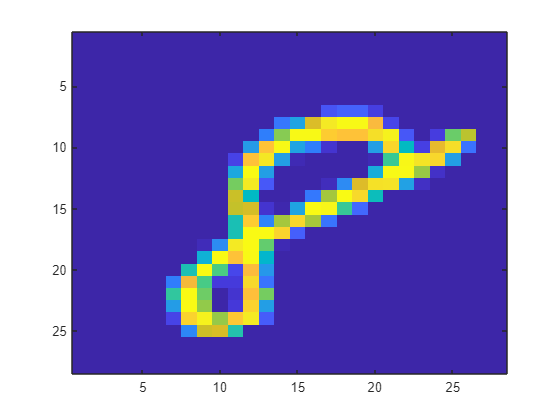

subplot(1, 3, 2), imagesc((reshape(mean(:,1,9),[28,28])));

ans =   handle to deleted Graphics


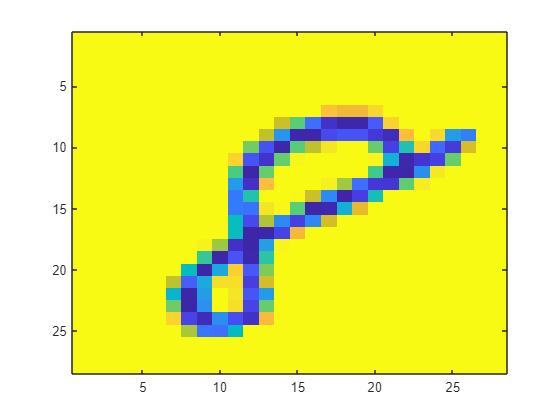

subplot(1, 3, 3), imagesc((reshape((mean(:,1,9)+(sqrt(eigenVal(28*28,1,9))).*eigenVec(:,28*28, 9)),[28,28])));

ans =   handle to deleted Graphics


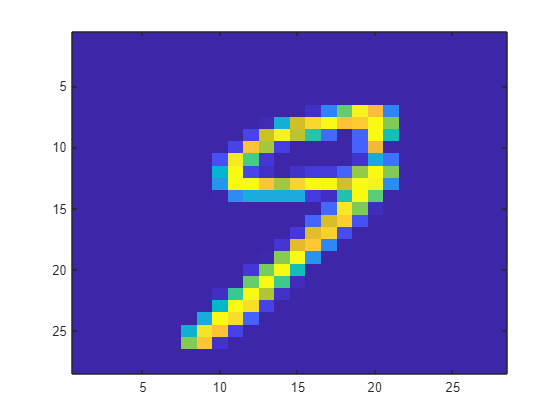


subplot(1, 3, 1), imagesc((reshape((mean(:,1,10)-(sqrt(eigenVal(28*28,1,10))).*eigenVec(:,28*28, 10)),[28,28])));

ans =   handle to deleted Graphics


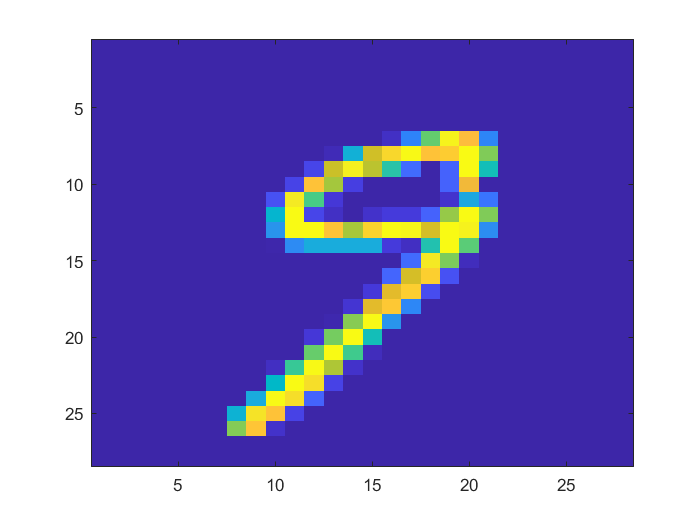

subplot(1, 3, 2), imagesc((reshape(mean(:,1,10),[28,28])));

ans =   handle to deleted Graphics


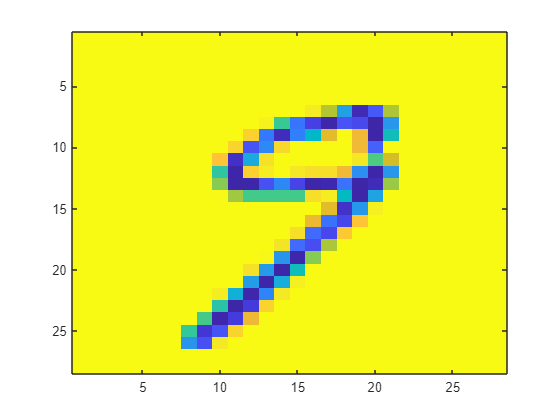

subplot(1, 3, 3), imagesc((reshape((mean(:,1,10)+(sqrt(eigenVal(28*28,1,10))).*eigenVec(:,28*28, 10)),[28,28])));